# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** :이진협        **

**학번**** :201716275**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

clear all;

x = [1,2,2,1];
N = 4;
X = dft(x,N)

X =    6.0000 + 0.0000i  -1.0000 - 1.0000i   0.0000 - 0.0000i  -1.0000 + 1.0000i


xn = idft(X,N)

xn =    1.0000 - 0.0000i   2.0000 - 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i


2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

clear all;

x = [1,2,2,1, zeros(1,12)];
N = 16;
X = dft(x,N)

X =    6.0000 + 0.0000i   4.6447 - 3.1035i   1.7071 - 4.1213i  -0.5727 - 2.8793i  -1.0000 - 1.0000i  -0.2557 - 0.0509i   0.2929 - 0.1213i   0.1838 - 0.2750i   0.0000 + 0.0000i   0.1838 + 0.2750i   0.2929 + 0.1213i  -0.2557 + 0.0509i  -1.0000 + 1.0000i  -0.5727 + 2.8793i   1.7071 + 4.1213i   4.6447 + 3.1035i


xn = idft(X,N)

xn =    1.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 - 0.0000i   1.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

clear all;
xtilde1 = [4,1,-1,1];
N = 4;
Xtilde1 = dft(xtilde1,N)

Xtilde1 =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

clear all;
xtilde2 = [1,0,-1,-1,0]; 
N = 5;
Xtilde2 = dft(xtilde2,N)

Xtilde2 =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

n = 0:100;
xn = sinc((n-50)/2).^2;
N = length(xn);
Xk = dft(xn,N) 

Xk =    1.9919 + 0.0000i  -1.9605 - 0.0610i   1.9167 + 0.1194i  -1.8732 - 0.1753i   1.8272 + 0.2285i  -1.7804 - 0.2791i   1.7317 + 0.3270i  -1.6822 - 0.3722i   1.6312 + 0.4145i  -1.5797 - 0.4541i   1.5269 + 0.4909i  -1.4738 - 0.5249i   1.4197 + 0.5560i  -1.3655 - 0.5843i   1.3105 + 0.6097i  -1.2558 - 0.6325i   1.2005 + 0.6522i  -1.1456 - 0.6694i   1.0905 + 0.6835i  -1.0360 - 0.6952i   0.9815 + 0.7038i  -0.9279 - 0.7101i   0.8745 + 0.7134i  -0.8222 - 0.7144i   0.7703 + 0.7126i  -0.7197 - 0.7086i   0.6698 + 0.7018i  -0.6214 - 0.6930i   0.5739 + 0.6815i  -0.5280 - 0.6682i   0.4832 + 0.6522i  -0.4403 - 0.6346i   0.3986 + 0.6146i  -0.3590 - 0.5930i   0.3208 + 0.5691i  -0.2847 - 0.5440i   0.2502 + 0.5167i  -0.2180 - 0.4884i   0.1876 + 0.4579i  -0.1595 - 0.4268i   0.1333 + 0.3936i  -0.1096 - 0.3602i   0.0879 + 0.3246i  -0.0687 - 0.2893i   0.0516 + 0.2518i  -0.0372 - 0.2151i   0.0248 + 0.1759i  -0.0151 - 0.1385i   0.0076 + 0.0978i  -0.0028 - 0.0608i


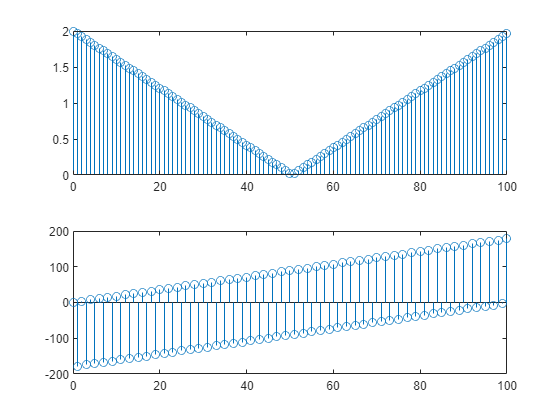

k = 0:N-1;
magXk = abs(Xk);
phaXk = angle(Xk)*180/pi;

subplot(2,1,1); stem(k,magXk);
subplot(2,1,2); stem(k,phaXk);

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

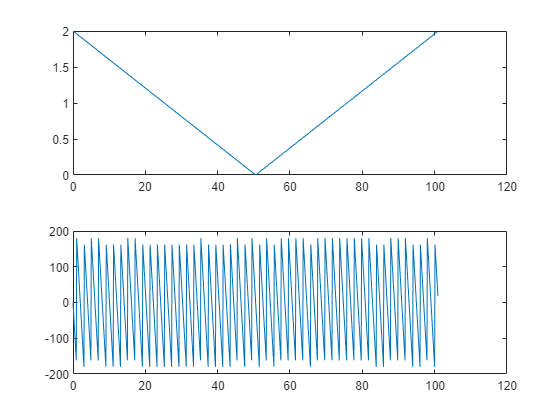

clear all;

n = 0:100;
xn = sinc((n-50)/2).^2;
N = length(xn);
[X,w] = freqz(xn,1,1000,'whole');
magX = abs(X); 
phaX = angle(X)*180/pi;
Dw = (2*pi)/N;
subplot(2,1,1); plot(w/Dw,magX);
subplot(2,1,2); plot(w/Dw,phaX);

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

 가능하다. 

function [Xk] = dft(xn,N)
         n = [0:1:N-1];
         k = [0:1:N-1];
         WN = exp(-j*2*pi/N);
         nk = n'*k;
         WNnk = WN .^ nk;
         Xk = xn * WNnk;
end

function [xn] = idft(Xk,N)
         n = [0:1:N-1];
         k = [0:1:N-1];
         WN = exp(-j*2*pi/N);
         nk = n'*k;
         WNnk = WN .^ (-nk);
         xn = (Xk * WNnk)/N;
end